# Homework 2

## Problem 5.18

## Problem 5.68

## [✔] ADSI Problem 1.4: Filter decomposition

### 1) Decompose a FIR filter with one zero outside the unit circle

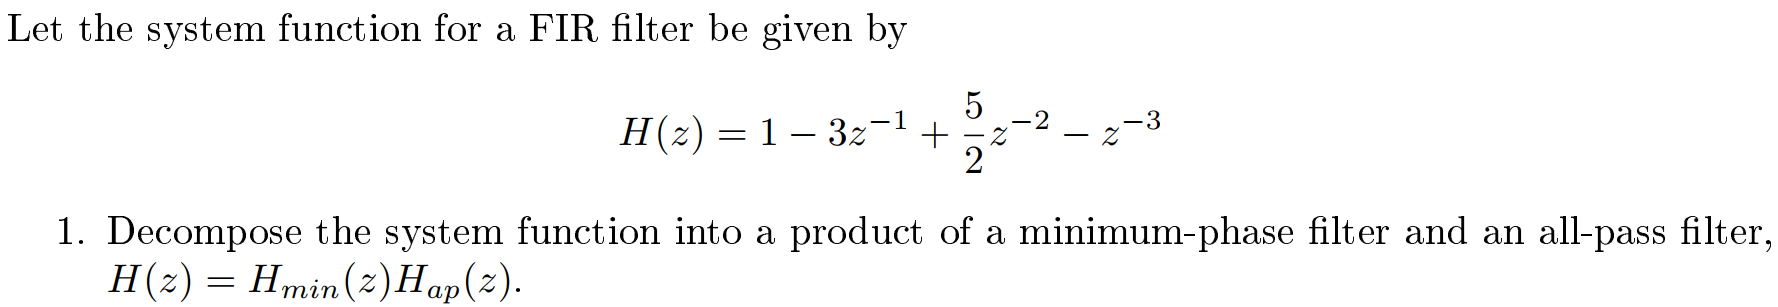

Any system funcrtion can be decomposed into a product of a minimum-phase filter and an all-pass filter using the following formula:

    
$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$
  

The minimum phase filter can be computed as follows:

    
$$H_{\min } \left(z\right)=\prod_i \;-\frac{1}{{a_i }^* }H_i \left(z\right)\left(1-a_i z^{-1} \right)$$


where $H_i \left(z\right)$ corresponds to the part of the transfer function where the i'th zero is inside the unit circle and $a_i =\frac{1}{{z_i }^* }$ and $z_i$ is the zero outside the unit circle.

The allpass filter can be calculated:

    
$$H_{\textrm{ap}} \left(z\right)=\prod_i \frac{z^{-1} -{a_i }^* }{1-a_i z^{-1} }\;$$


The filter decomposition algorithm has following steps:

- convert transfer function into pole-zero representation in order to find the zeros that are outside the unit circle

- compute $a$ and its conjugate $a^*$

- find $H_1 \left(z\right)$ which corresponds to the part of the transfer function where zeros are inside the unit circle

- plugin the numbers for the formula for the minimum-phase filter

- plugin the numbers for the formula for the allpass filter 

- put everything together:

**Step 1:** convert transfer function into pole-zero representation in order to find the zeros that are outside the unit circle

syms z;
rts = roots([1, -3, 5/2, -1])

H_outside = 1; % Represents part of H where zeros are outside the unit circle
H_inside = 1;  % Represents part of H where zeros are inside the unit circle
zeros_outside = [];
for i = 1:numel(rts)
    root = rts(i);
    if abs(root) > 1
        H_outside = H_outside * (1 - root*z^-1);
        zeros_outside = [zeros_outside; root];
    else
        H_inside = H_inside * (1 - root*z^-1);
    end
end


rts =    2.0000 + 0.0000i
   0.5000 + 0.5000i
   0.5000 - 0.5000i


z0 = 0;
if numel(zeros_outside) == 1
    z0 = zeros_outside(1);
else
    disp('Something is wrong! The transfer function has more than one zero outside the unit circle')
end

H_outside = expand(H_outside);
H_inside = expand(H_inside);

% Sanity check
H = expand(H_inside * H_outside)

The zero-pole representation of the transfer function is:

H_outside
H_inside
zplane([1, -1, 1/2]) % Should all have zeros inside the unit circle


$$H\left(z\right)=\left(1-2z^{-1} \right)\left(1-z^{-1} +\frac{1}{2}z^{-2} \right)$$


% Sanity check
conv([1, -2], [1, -1, 1/2])

To find the zero $z_0$ that is outside the unit circle, we can plot zplane:

zplane([1, -3, 5/2, -1]);

In this exercise, the zero outside the unit circle is $z_0 =2$.

z0

$$H = \frac{5}{2\,z^{2}}-\frac{3}{z}-\frac{1}{z^{3}}+1$$

**Step 2:** compute $a$ and its conjugate $a^*$

a = 1/z0

$$H\_outside = 1-\frac{2}{z}$$

a_conj = conj(a)

$$H\_inside = \frac{1}{2\,z^{2}}-\frac{1}{z}+1$$


$$a=\frac{1}{z_0 }=\frac{1}{2}$$



$$a^* ={\left(\frac{1}{z_0 }\right)}^* ={\left(\frac{1}{2}\right)}^* =\frac{1}{2}$$


**Step 3:** find $H_1 \left(z\right)$ which corresponds to the part of the transfer function where zeros are inside the unit circle

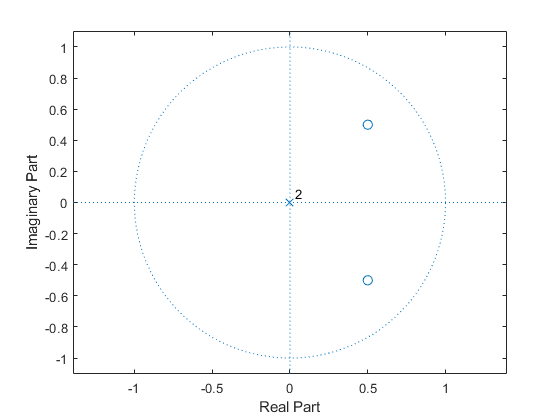

H_inside

The zero-pole representation of the transfer function is:


$$H\left(z\right)=\left(1-2z^{-1} \right)\left(1-z^{-1} +\frac{1}{2}z^{-2} \right)$$


therefore $H_1 \left(z\right)$is


$$H_1 \left(z\right)=1-z^{-1} +\frac{1}{2}z^{-2}$$


**Step 4**: plugin the numbers for the formula for minimum-phase filter


$$H_{\min } \left(z\right)=-\frac{1}{a^* }H_1 \left(z\right)\left(1-az^{-1} \right)$$



$$\begin{array}{l}
H_{\min } \left(z\right)=-\frac{1}{\left(\frac{1}{2}\right)}\left(1-z^{-1} +\frac{1}{2}z^{-2} \right)\left(1-0\ldotp 5z^{-1} \right)\\
H_{\min } \left(z\right)=-2\left(1-z^{-1} +\frac{1}{2}z^{-2} \right)\left(1-0\ldotp 5z^{-1} \right)
\end{array}$$


-2 * conv([1, -1, 1/2], [1, -0.5])

ans =     1.0000   -3.0000    2.5000   -1.0000



$$H_{\min } \left(z\right)=-2+3z^{-1} -2z^{-2} +\frac{1}{2}z^{-3}$$


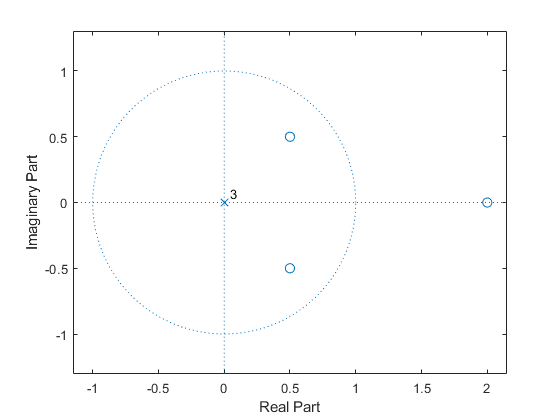

H_min = expand((-1/a_conj) * H_inside * (1 - a*z^-1))

H_min_b = [-2, 3, -2, 1/2];
H_min_rts = roots(H_min_b)

z0 = 2

isminphase(H_min_b)
zplane(H_min_b)

**Step 5:** compute the allpass filter :


$$H_{\mathrm{ap}} \left(z\right)=\frac{z^{-1} -a^* }{1-az^{-1} }$$



$$H_{\mathrm{ap}} \left(z\right)=\frac{z^{-1} -0\ldotp 5}{1-0\ldotp 5z^{-1} }$$


H_ap = (z^-1 - a_conj) / (1 - a*z^-1)

a = 0.5000

**Step 6:** put everything together:


$$\begin{array}{l}
H_{\min } \left(z\right)=-2+3z^{-1} -2z^{-2} +\frac{1}{2}z^{-3} \\
H_{\textrm{ap}} \left(z\right)=\frac{z^{-1} -0\ldotp 5}{1-0\ldotp 5z^{-1} }
\end{array}$$



$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$



$$H\left(z\right)=\left(-2+3z^{-1} -2z^{-2} +\frac{1}{2}z^{-3} \right)\left(\frac{z^{-1} -0\ldotp 5}{1-0\ldotp 5z^{-1} }\right)$$


### 2) Show that the system and its correspond minimum-phase have the same magnitude response

To show that $H\left(z\right)$ and $H_{\mathrm{min}} \left(z\right)$ have the same magnitude response, we can plot them. If the two graphs are on top of each other then then they have the same magnitude response.

% Coefficients for H(z)

a_conj = 0.5000

b = [1, -3, 5/2, -1];
a = 1;
[H, w] = freqz(b,a,'whole');

% Coefficients for H_min(z)

$$H\_inside = \frac{1}{2\,z^{2}}-\frac{1}{z}+1$$

H_min_b = [-2, 3, -2, 1/2];
H_min_a = 1;
[H_min_z, H_min_w] = freqz(H_min_b, H_min_a, 'whole');
% plot(H_min_w, log10(abs(H_min_z)));

% The offset ensures that the two graphs are not on top of each other
offset = -0.2;
plot(w, abs(H), H_min_w, abs(H_min_z) + offset); 
set(gca,'XTick',0:pi/2:2*pi)

ans =    -2.0000    3.0000   -2.0000    0.5000


set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
xlabel('Frequency (rad/sample)')

$$H\_min = \frac{3}{z}-\frac{2}{z^{2}}+\frac{1}{2\,z^{3}}-2$$

ylabel('Magnitude Response')
xlim([0, 2*pi]);

H_min_rts =    0.5000 + 0.5000i
   0.5000 - 0.5000i
   0.5000 + 0.0000i


### 3) Decompose a filter that has two zeros outside the unit circle

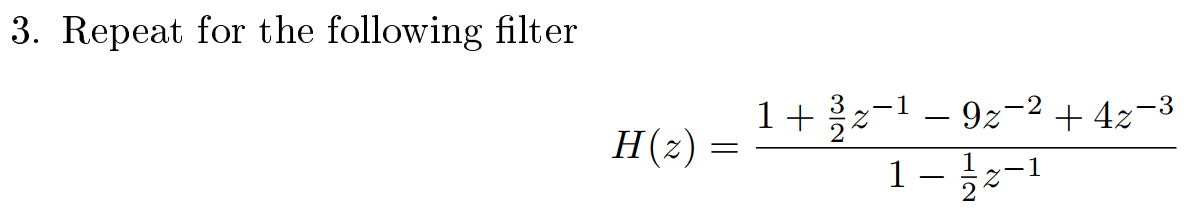

b = [1, 3/2, -9, 4];

ans = logical
   1


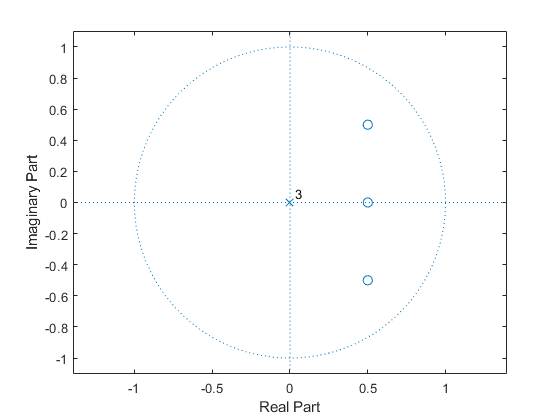

a = [1, -1/2];

Plot the zeros and the poles:

zplane(b, a);

$$H\_ap = -\frac{\frac{1}{z}-\frac{1}{2}}{\frac{1}{2\,z}-1}$$

From the plot, we can see that there is a zero and a pole at 0.5. They will cancel each other.

% Find the zeros of H
rts = roots(b)

Now, the transfer function can be rewritten as:


$$H\left(z\right)=\frac{\left(1-\left(-4\right)z^{-1} \right)\left(1-2z^{-1} \right)\left(1-\frac{1}{2}z^{-1} \right)}{1-\frac{1}{2}z^{-1} }=\left(1-\left(-4\right)z^{-1} \right)\left(1-2z^{-1} \right)=\left(1-\left(-4\right)z^{-1} \right)\left(1-2z^{-1} \right)$$


Let us find the coefficients of the rewritten transfer function:

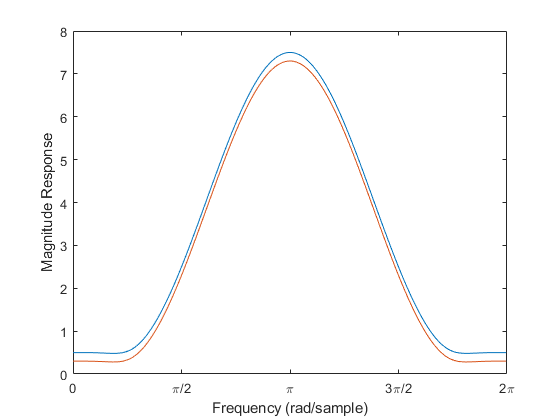

H_new = expand((1+4*z^-1) * (1-2*z^-1))
% Automatically extract the coefficients
b_new = coeffs(expand(H_new * z^2), 'all')
% Find the zeros of H_new
rts = roots(b_new)
syms z;
H_outside = 1; % Represents part of H where zeros are outside the unit circle
H_inside = 1;  % Represents part of H where zeros are inside the unit circle
zeros_outside = [];
for i = 1:numel(rts)
    root = rts(i);
    if abs(root) > 1
        H_outside = H_outside * (1 - root*z^-1);
        zeros_outside = [zeros_outside; root];
    else
        H_inside = H_inside * (1 - root*z^-1);
    end
end

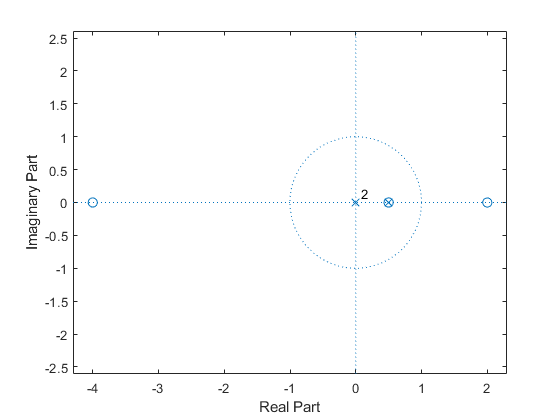


% Sanity check
H = expand(H_inside * H_outside)
% Finally compute the H_min and H_ap
H_min = 1;
H_ap = 1;
for i = 1:numel(zeros_outside)
    a = 1/zeros_outside(i);

    a_conj = conj(a);
    H_min = H_min * (-1/a_conj) * H_inside * (1 - a*z^-1);
    H_ap = H_ap * ((z^-1 - a_conj) / (1 - a*z^-1));

rts =    -4.0000
    2.0000
    0.5000


end

% Check that H_min is in fact minimum-phase
% Check that all zeros are within the unit circle!

$$H\_new = \frac{2}{z}-\frac{8}{z^{2}}+1$$

H_min_b = coeffs(expand(H_min * z^10), 'all');
zplane(H_min_b)

$$b\_new = \left(\begin{array}{ccc} 1 & 2 & -8 \end{array}\right)$$

% Display H_min
expand(H_min)

$$rts = \left(\begin{array}{c} -4\\ 2 \end{array}\right)$$

We can write $H_{\mathrm{min}} \left(z\right)=-8+2z^{-1} +z^{-2}$

% Display H_ap in order to rewrite it
H_ap

Expanding the numerator, we get:

H_ap_num = expand(-1*(1/z - 1/2)*(1/z + 1/4))
H_ap_den= expand((1/(2*z) - 1)*(1/(4*z) + 1))

We can multiply both the numerator and denominator with 8, to get nice numbers:

(H_ap_num * 8) / (H_ap_den * 8)

Now, we can write the transfer function for the allpass filter:


$$H_{\mathrm{ap}} \left(z\right)=\frac{1+2z^{-1} -8z^{-2} }{-8+2z^{-1} +z^{-2} }$$


So we have:


$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$


where $H_{\min } \left(z\right)=-8+2z^{-1} +z^{-2}$ and $H_{\textrm{ap}} \left(z\right)=\frac{1+2z^{-1} -8z^{-2} }{-8+2z^{-1} +z^{-2} }$

To show that $H\left(z\right)$ and $H_{\mathrm{min}} \left(z\right)$ have the same magnitude response, we can plot them. If the two graphs are on top of each other then then they have the same magnitude response.


$$H\left(z\right)=\frac{1+\frac{3}{2}z^{-1} -9z^{-2} +4z^{-3} }{1-\frac{1}{2}z^{-1} }$$



$$H_{\min } \left(z\right)=-8+2z^{-1} +z^{-2}$$


% Coefficients for H(z)
b = [1, 3/2, -9, 4];

$$H = \frac{2}{z}-\frac{8}{z^{2}}+1$$

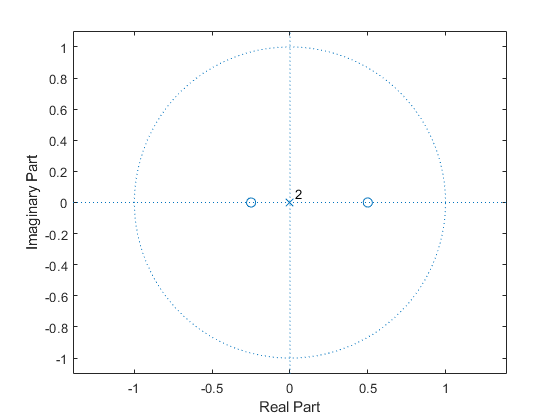

a = [1, -1/2];
[H, w] = freqz(b,a,'whole');

% Coefficients for H_min(z)
H_min_b = [-8, 2, 1];
H_min_a = 1;
[H_min_z, H_min_w] = freqz(H_min_b, H_min_a, 'whole');
% plot(H_min_w, log10(abs(H_min_z)));

% The offset ensures that the two graphs are not on top of each other
offset = -0.2;
plot(w, abs(H), H_min_w, abs(H_min_z) + offset); 
set(gca,'XTick',0:pi/2:2*pi)
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})

xlabel('Frequency (rad/sample)')
ylabel('Magnitude Response')
xlim([0, 2*pi]);

$$ans = \frac{2}{z}+\frac{1}{z^{2}}-8$$

## [✔] ADSI Problem 1.5 Filter decomposition

### 1) Show that a FIR filter with a difference equation is not minimum-phase

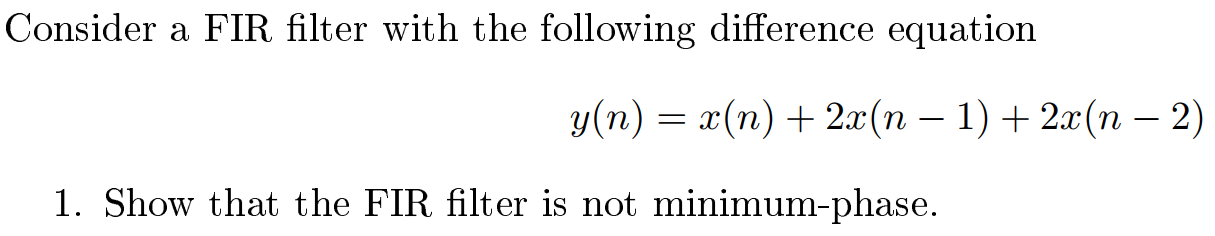

To determine whether the filter is a minimum-phase or not, we need get the transfer function of this FIR filter $H\left(z\right)$ which is defined as:


$$H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{b_0 +b_1 z^{-1} +b_2 z^{-2} \cdots +b_M z^{-M} }{1+a_1 z^{-1} +a_2 z^{-2} \cdots +a_N z^{-N} }$$


This means that we must take the z-transform of difference equation:


$$\begin{array}{l}
Y\left(z\right)\;=X\left(z\right)+2X\left(z\right)z^{-1} +2X\left(z\right)z^{-2} \\
Y\left(z\right)\;=X\left(z\right)\left(1+2z^{-1} +2z^{-2} \right)\\
\frac{Y\left(z\right)}{X\left(z\right)}=1+2z^{-1} +2z^{-2} \\
H\left(z\right)=1+2z^{-1} +2z^{-2} 
\end{array}$$


Once we have the transfer function, we can determine if the filter is a minimum-phase by looking at the zplane plot:

zplane([1, 2, 2])

$$H\_ap = -\frac{\left(\frac{1}{z}-\frac{1}{2}\right)\,\left(\frac{1}{z}+\frac{1}{4}\right)}{\left(\frac{1}{2\,z}-1\right)\,\left(\frac{1}{4\,z}+1\right)}$$

Since all the zeros are outside the unit cirlce, clearly the given FIR filter is not minimum-phase. It is a **maximum-phase**.

### 2) Find the difference equation for the corresponding minimum-phase FIR filter

We found that the transfer function for the difference equation is:


$$H\left(z\right)=1+2z^{-1} +2z^{-2}$$


% Find the zeros of H
rts = roots([1, 2, 2])

$$H\_ap\_num = \frac{1}{4\,z}-\frac{1}{z^{2}}+\frac{1}{8}$$

syms z;

$$H\_ap\_den = \frac{1}{4\,z}+\frac{1}{8\,z^{2}}-1$$

H_outside = 1; % Represents part of H where zeros are outside the unit circle
H_inside = 1; % Represents part of H where zeros are inside the unit circle

$$ans = \frac{\frac{2}{z}-\frac{8}{z^{2}}+1}{\frac{2}{z}+\frac{1}{z^{2}}-8}$$

zeros_outside = [];
for i = 1:numel(rts)
    root = rts(i);
    if abs(root) > 1
        H_outside = H_outside * (1 - root*z^-1);
        zeros_outside = [zeros_outside; root];
    else
        H_inside = H_inside * (1 - root*z^-1);
    end
end
% Sanity check
H = expand(H_inside * H_outside)
% Finally compute the H_min and H_ap
H_min = 1;
H_ap = 1;
for i = 1:numel(zeros_outside)
    a = 1/zeros_outside(i);
    a_conj = conj(a);
    H_min = H_min * (-1/a_conj) * H_inside * (1 - a*z^-1);
    H_ap = H_ap * ((z^-1 - a_conj) / (1 - a*z^-1));
end

% Check that H_min is in fact minimum-phase
% Check that all zeros are within the unit circle!
H_min_b = coeffs(expand(H_min * z^10), 'all');
zplane(H_min_b)

From the zero-pole plot we can see that we have a minimum-phase filter.

Finally, we can write out the transfer function of the minimum-phase part:

expand(H_min)


$$H_{\mathrm{min}} \left(z\right)=2+2z^{-1} +z^{-2}$$


H_ap

Let us simply this expression:

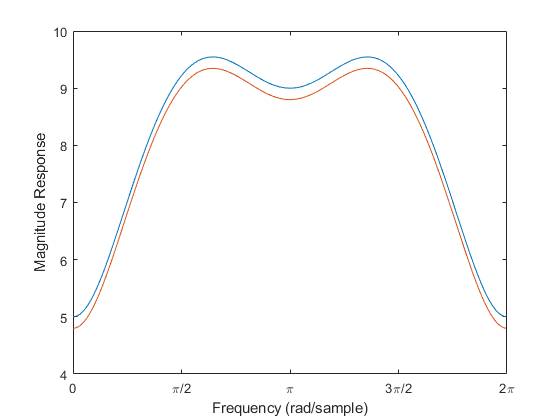

H_ap_num = expand((1/z + 1/2 - 1/2i) * (1/z + 1/2 + 1/2i))

H_ap_den = expand((1+ (1/2 -1/2i)*z^-1) * (1 + (1/2+1/2i)*z^-1 ))


$$H_{\mathrm{ap}} \left(z\right)=\frac{\frac{1}{2}+z^{-1} +z^{-2} }{1+z^{-1} +\frac{1}{2}z^{-2} }$$


Hence:


$$\begin{array}{l}
H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)\\
H\left(z\right)=\left(2+2z^{-1} +z^{-2} \right)\left(\frac{\frac{1}{2}+z^{-1} +z^{-2} }{1+z^{-1} +\frac{1}{2}z^{-2} }\right)
\end{array}$$


We can write $H_{\mathrm{min}} \left(z\right)=2+2z^{-1} +z^{-2}$ as difference equation:


$$\begin{array}{l}
H_{\mathrm{min}} \left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}\\
Y\left(z\right)=X\left(z\right)\left(2+2z^{-1} +z^{-2} \right)
\end{array}$$


Now, we take the inverse z-transform:

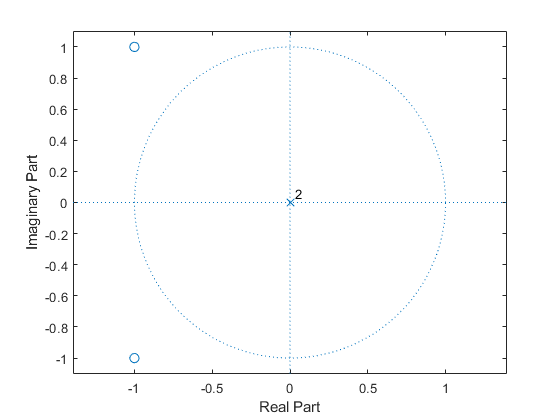

rts =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


$$H = \frac{2}{z}+\frac{2}{z^{2}}+1$$

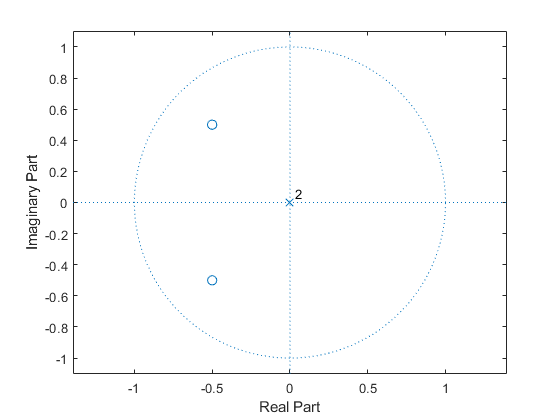

$$ans = \frac{2}{z}+\frac{1}{z^{2}}+2$$

$$H\_ap = \frac{\left(\frac{1}{z}+\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\,\left(\frac{1}{z}+\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)}{\left(1+\frac{\frac{1}{2}-\frac{1}{2}\,\mathrm{i}}{z}\right)\,\left(1+\frac{\frac{1}{2}+\frac{1}{2}\,\mathrm{i}}{z}\right)}$$

$$H\_ap\_num = \frac{1}{z}+\frac{1}{z^{2}}+\frac{1}{2}$$

$$H\_ap\_den = \frac{1}{z}+\frac{1}{2\,z^{2}}+1$$

$$ans = 2\,\delta_{n-1,0}+\delta_{n-2,0}+2\,\delta_{n,0}$$

iztrans(2 + 2*z^-1 + z^-2)

We get:


$$y\left\lbrack n\right\rbrack =2x\left\lbrack n\right\rbrack +2x\left\lbrack n-1\right\rbrack +x\left\lbrack n-2\right\rbrack$$


## ADSI Problem 1.8: Designing all-pass filters

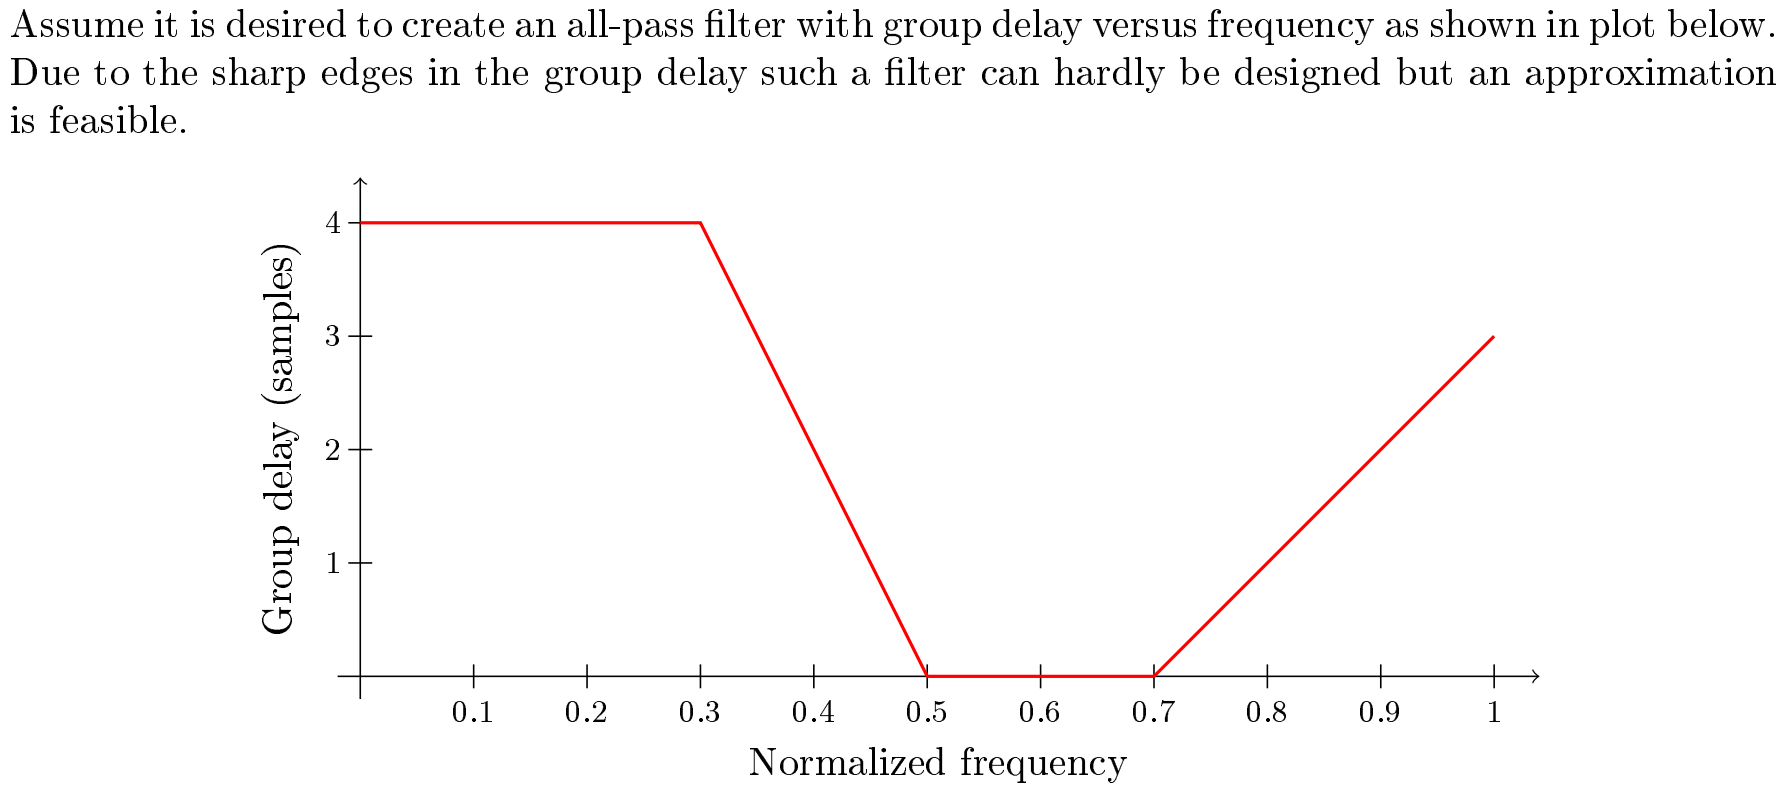

### 1) Use iirgrpdelay in MATLAB to design a 4th order all-pass filter. You can set edges=[0 1]  

A 4th order allpass filter has the following transfer function


$$H_{\mathrm{ap}} \left(z\right)=\prod_i \frac{z^{-1} -p_i^* }{1-p_i z^{-1} }=\frac{\left(z^{-1} -p_1^* \right)\left(z^{-1} -p_2^* \right)\left(z^{-1} -p_3^* \right)\left(z^{-1} -p_4^* \right)}{\left(1-p_1 z^{-1} \right)\left(1-p_2 z^{-1} \right)\left(1-p_3 z^{-1} \right)\left(1-p_4 z^{-1} \right)}$$


where $p_i$ corresponds to the i'th pole.

The magnitude reposponse of an allpass filter is constant for all frequencies, however its phase response may different. For this reason, allpass filters are used for **delay equalisation**.

### 2) What happens as you increase the order of the filter?

### 3) What order of the filter is necessary to bring the maximum group delay error below 0.5 samples?

### 4) Plot the impulse response of the filter. Does the length of the impulse response match your expectations.  